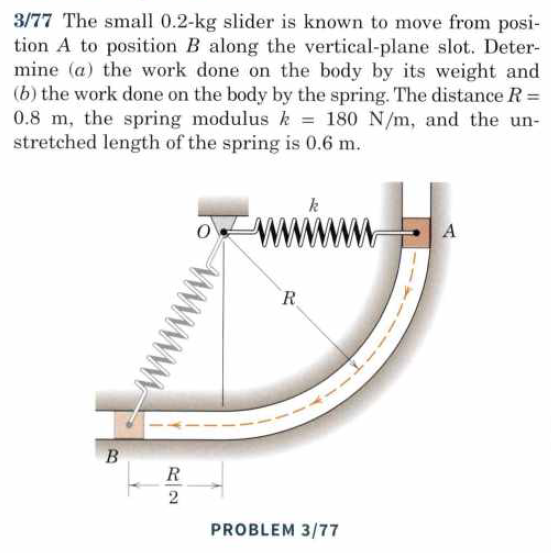

fprintf("3.77")

3.77


u = symunit;

m = 0.2 * u.kg;
R = 0.8 * u.m;

L_fjeder = 0.6 * u.m;

k = 180 * u.N/u.m;

g = 9.81 * u.m/u.s^2;

% Work on body by mass
y2 = 0;
y1 = R;

U_12_body =vpa(-m*g*(y2 - y1), 4)

$$U\_12\_body = 1.57\,\frac{\mathrm{kg}\,m^{2}}{s^{2}}$$




% Work on body by spring
x2 = (R - L_fjeder)

$$x2 = \frac{1}{5}\,m$$

x1 = vpa(sqrt((R/2)^2 + R^2) - L_fjeder,3)

$$x1 = 0.294\,m$$


% Her er k ikke negativ, da fjederen er blevet forlænget
U_12_spring = vpa(k/2 * (x2^2 - x1^2), 4)

$$U\_12\_spring = -4.202\,N\,m$$

# Opgave 3.80

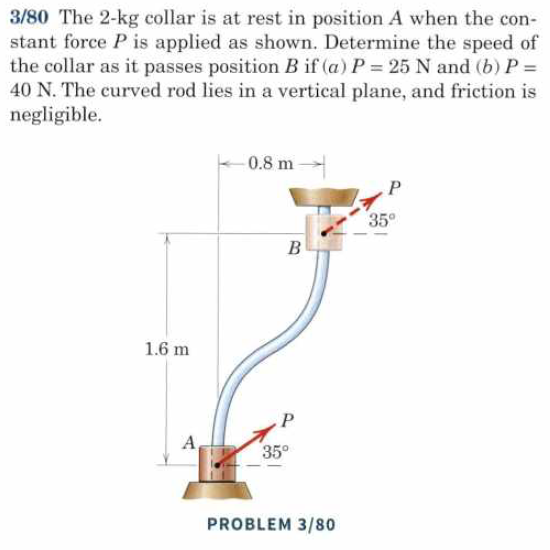

fprintf("3.80")

3.80


clc
clear
u = symunit;

m = 2*u.kg;
g = 9.81 * u.m/u.s^2;

theta = 35

theta =     35



P = [25, 40] * u.N;

% Kraftkomposanter
Px = P*cosd(theta);     Py = P*sind(theta);

% Positioner
x1 = 0 * u.m;     x2 = 0.8 * u.m;

y1 = 0 * u.m;     y2 = 1.6 * u.m;

% Udregninger
delta = Px * (x2 - x1);     alpha = (-m*g + Py)*(y2-y1);

vx = sqrt(2*delta/m);   vy = sqrt(2*alpha/m);

v = sqrt(vx.^2 + vy.^2);

P_y = vpa(simplify(unitConvert(Py, u.N)), 3)

$$P\_y = \left(\begin{array}{cc} 14.3\,N & 22.9\,N \end{array}\right)$$


V_tots = vpa(simplify(unitConvert(v,"SI")),3)

$$V\_tots = \left(\begin{array}{cc} 2.82\,\frac{m}{s} & 5.62\,\frac{m}{s} \end{array}\right)$$

# Opgave 3.82

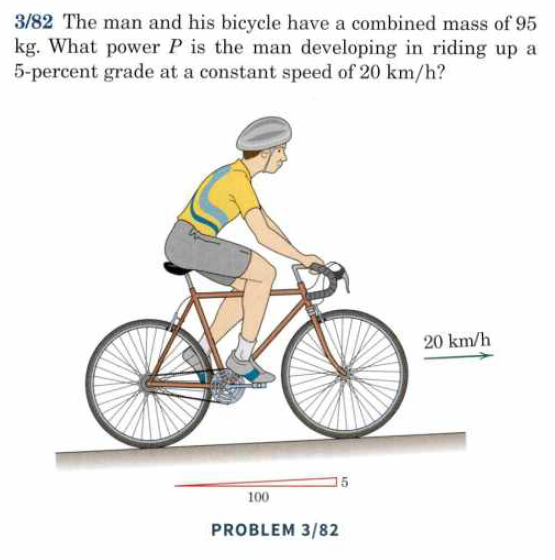

fprintf("3.82")

3.82


clc
clear
u = symunit;

m = 95 * u.kg;
g = 9.81 * u.m/u.s^2;

theta = atan(5/100);


% Hastigheder
v = 20 * u.km/u.hr;

% Effekt = m g v sin(theta)
P = m * g * v * sin(theta);
vpa(unitConvert(P, "SI"),4)

$$ans = 258.6\,\frac{\mathrm{kg}\,m^{2}}{s^{3}}$$

# Opgave 3.85

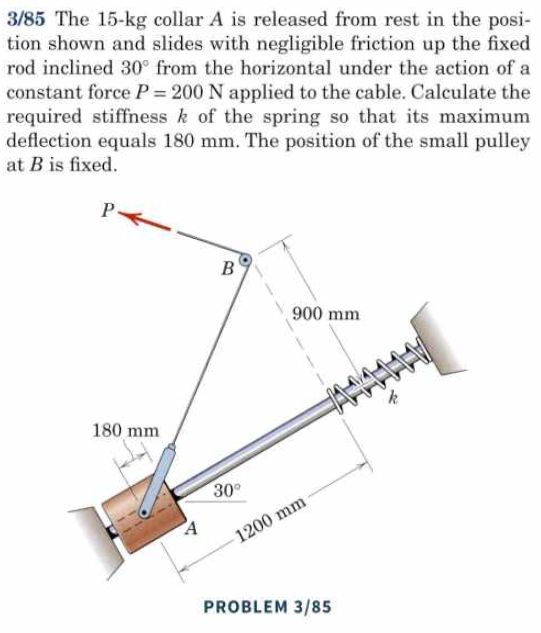

clc
clear
u = symunit;

m = 15 * u.kg;
g = 9.81 * u.m/u.s^2;

P = 200 * u.N;

a = 1200 * u.mm;
b = 900 * u.mm;
c = sqrt(a^2 + b^2);

v = c - b;

theta = 30;

x = 180 * u.mm;



k = 2/x^2 * (P*v - m*g*sind(theta)*a);

vpa(unitConvert(k, "SI"),4)

$$ans = 1957.0\,\frac{\mathrm{kg}}{s^{2}}$$

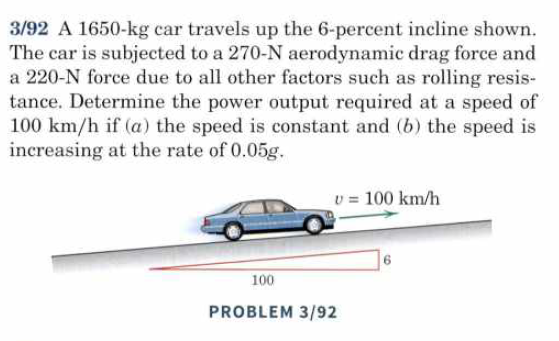

clear
g = 9.81;
m = 1650;
v = 100/3.6;

w = m*g;

Fneg = 270+220;

rise = 6;
run = 100;
theta = atan(rise/run);

syms F
Fx = F - Fneg - w*sin(theta) == 0;
F = vpa(solve(Fx, F), 4) % Kraften der bilen skal overkomme for at køre

$$F = 1459.0$$


% Effekten 
P = vpa(F*v, 4)% watt

$$P = 40540.0$$


a = 0.05*g;

syms F
Fx = F - Fneg - w*sin(theta) == m*a;
F = vpa(solve(Fx, F), 4) % Kraften der bilen skal overkomme for at køre

$$F = 2269.0$$


% Effekten 
P = vpa(F*v, 4)% watt

$$P = 63020.0$$

# Opgave 3.111

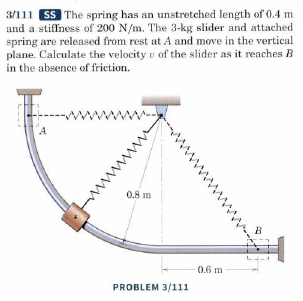

clc
clear
u = symunit;

m = 3 * u.kg;   g = 9.81 * u.m/u.s^2;

k = 200 * u.N/u.m;  R = 0.8 * u.m; l_b = 0.6 * u.m; l_f = 0.4*u.m;

x2 = sqrt(R^2 + l_b^2) - l_f;
x1 = R - l_f;

delta_x = x2^2 - x1^2;

y2 = R;     y1 = 0;     delta_y = y2 - y1;

v_2 = sqrt(2*g*delta_y - k*delta_x/m);

vpa(simplify(unitConvert(v_2, "SI")),4)

$$ans = 1.537\,\frac{m}{s}$$

# Opgave 3.121

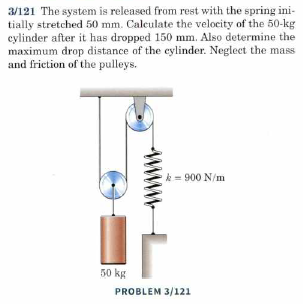

fprintf("3.121")

3.121


clc
clear
u = symunit;

m = 50 * u.kg;   g = 9.81 * u.m/u.s^2;

x1 = 50*u.mm; x2 = 150*u.mm; k = 900*u.N/u.m; delta_x = x1 + 2*x2;

v2 = sqrt(k*x1^2/m - k*delta_x^2/m + 2*g*x2);
vpa(simplify(unitConvert(v2, "SI")),3)

$$ans = 0.885\,\frac{m}{s}$$


syms xd
eqn = k/2*(x1 + 2*xd)^2 == k/2 * x1^2 + m*g*xd;

delta_x_max = solve(eqn, xd);
vpa(simplify(unitConvert(delta_x_max, "SI")),4)

$$ans = \left(\begin{array}{c} 0\\ 0.2225\,m \end{array}\right)$$

# Opgave 3.125

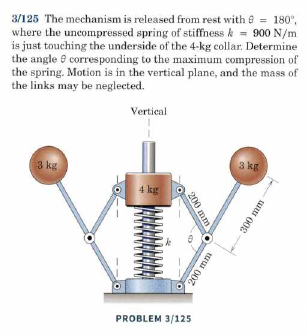

fprintf("3.125")

3.125


clc
clear
u = symunit;

g = 9.81 * u.m/u.s^2;

m1 = 4*u.kg; m2 = 3*u.kg;

syms theta

y2 = 0.4*u.m; y1 = y2*sind(theta/2); 
y4 = 0.5*u.m; y3 = y4*sind(theta/2);

k = 900 * u.N/u.m;

eqn = k/2*(y2 - y1)^2 - m1*g*(y2 - y1) - 2*m2*g*(y4 - y3)==0;

theta = solve(eqn, theta);
vpa(simplify(unitConvert(theta, "SI")),4)

$$ans = \left(\begin{array}{c} 180.0\\ 43.83\\ 316.2 \end{array}\right)$$


thetaa = asind(1-2*m1*g/(k*y2) - 4*m2*g*y4/(k*y2^2)) * 2;
vpa(simplify(unitConvert(thetaa, "SI")),4)

$$ans = 43.83$$


fprintf("løst med både solve og ved isolering")

løst med både solve og ved isolering

# Opgave 1.131

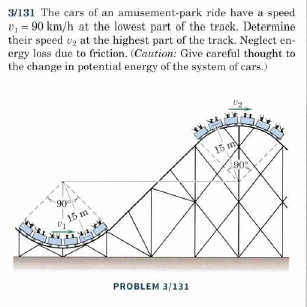

fprintf("3.131")

3.131


clc
clear
u = symunit;

g = 9.81 * u.m/u.s^2;

v1 = 90*u.km/u.hr; y1 = 15*u.m; r = 2*sqrt(2)*y1/pi; y2 = 2*r; 

v2 = sqrt(v1^2 - 2*g*y2);

vpa(simplify(unitConvert(v2, "SI")),4)

$$ans = 9.751\,\frac{m}{s}$$